# LQG (Original Non-Linear System)

x_initial = [50;0;30;0;10;0;0;0;0;0;0;0]

x_initial =     50
     0
    30
     0
    10
     0
     0
     0
     0
     0
     0
     0


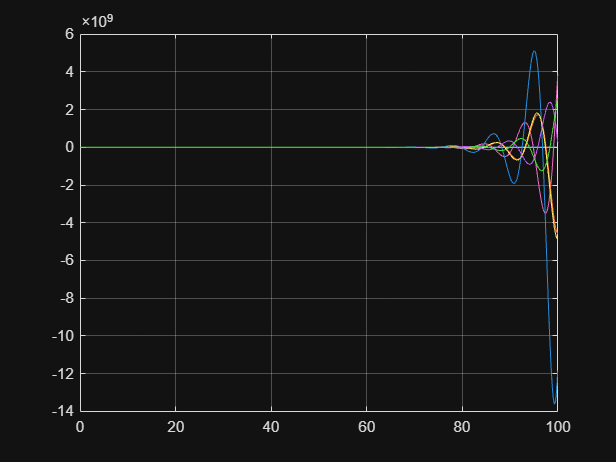

tspan = 0:0.1:100;
[t,x] = ode45(@lqg_non_linear,tspan,x_initial);
plot(t,x)
grid on

##  Function lqg_non_linear for Non-Linear LQG control

function dydt = lqg_non_linear(~,y)
M = 1000; 
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;

A=[0 1 0 0 0 0;
   0 0 -(m1*g)/M 0 -(m2*g)/M 0;
   0 0 0 1 0 0;
   0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
   0 0 0 0 0 1;
   0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];

R = 0.1;

% From the previous case, we have determined that only C1, C3 and C4 were
% observable. Hence, we are going to consider only these 3 cases.

C1 = [1 0 0 0 0 0];  % x(t)
% C3 = [1 0 0 0 0 0; 0 0 0 0 1 0]; % x(t) and theta2(t)
% C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; % x(t), theta1(t) & theta2(t)

% D = 0; 
K_val = lqr(A,B,Q,R);
F = -K_val*y(1:6);

vd = 0.3*eye(6);
vn = 1;
K_pop = lqr(A',C1',vd,vn)';
%K_pop3 = lqr(A',C2',vd, vn)';

sd = (A-K_pop*C1)*y(7:12);
%sd2 = (A-K_pop3*C1)*y(7:12);

dydt=zeros(12,1);
% y(1) = x; y(2) = xdot; y(3) = theta1;   y(4) = theta1dot;  
% y(5) = theta2;    y(6) = theta2dot;

dydt(1) = y(2);
dydt(2)=(F-(g/2)*(m1*sind(2*y(3))+m2*sind(2*y(5)))-(m1*l1*(y(4)^2)*sind(y(3)))-(m2*l2*(y(6)^2)*sind(y(5))))/(M+m1*((sind(y(3)))^2)+m2*((sind(y(5)))^2));%xDD
dydt(3)= y(4);
dydt(4)= (dydt(2)*cosd(y(3))-g*(sind(y(3))))/l1';
dydt(5)= y(6);
dydt(6)= (dydt(2)*cosd(y(5))-g*(sind(y(5))))/l2;
dydt(7)= y(2)-y(10); 
dydt(8)= dydt(2)-sd(2);
dydt(9)= y(4)-y(11);
dydt(10)= dydt(4)-sd(4);
dydt(11)= y(6)-y(12);
dydt(12)= dydt(6)-sd(6);

end